Name = ["Bravo Gift";"Austine NASASIRA";"Patricia Namuwawu";"Nyemere Anna Grace";"Kintu Gadaffi";"Jeremiah Ainamatsiko";"Mugume Mathias";"Aburot Martha";"Barasa Elvis";"Acham Royce"];
Age = [21;22;21;22;22;21;22;26;23;22;];
Tribe = ["alur";"munyankole";"muganda";"itesot";"muganda";"munyankole";"munyankole";"itesot";"samia";"langi"];
District = ["pakwach";"bushenyi";"masaka";"butebo";"mityana";"kazo";"bushenyi";"amuria";"busia";"lira"];
Hobby = ["music";'dancing';"reading";"footbal";"swimming";"music";"praying";"adventure";"football";"adventure"];
YearofBirth = [2004;2003;2004;2003;2003;2004;2003;1999;2002;2003];
IncomeLevel = [23;34;68;90;23;12;6;23;45;89];
WeeksAttended = [8;9;10;11;12;13;10;11;14;15];
MarksScored = [51;56;79;90;89;67;56;54;53;60];
Course = ["PTI";"WAR";"APE";"AMI";"AMI";"WAR";"MEB";"WAR";"AMI";"AMI"];
Religion = ["catholic";"catholic";"anglican";"catholic";"muslim";"anglican";"catholic";"anglican";"anglican";"catholic"];


Creating our Table

Students = table(Name,Age,Tribe,District,Hobby,YearofBirth,IncomeLevel,WeeksAttended,MarksScored,Course,Religion);
disp(Students);

             Name             Age       Tribe         District        Hobby       YearofBirth    IncomeLevel    WeeksAttended    MarksScored    Course     Religion 
    ______________________    ___    ____________    __________    ___________    ___________    ___________    _____________    ___________    ______    __________

    "Bravo Gift"              21     "alur"          "pakwach"     "music"           2004            23               8              51         "PTI"     "catholic"
    "Austine NASASIRA"        22     "munyankole"    "bushenyi"    "dancing"         2003            34               9           

## STATISTICAL ANALYSIS

## distribution of religion


Religion_distribution = groupsummary(Students,"Religion");
disp(Religion_distribution(:,["Religion","GroupCount"]));

     Religion     GroupCount
    __________    __________

    "anglican"        4     
    "catholic"        5     
    "muslim"          1     



## distribution of tribes


Tribe_distribution = groupsummary(Students,"Tribe");
disp(Tribe_distribution(:,["Tribe","GroupCount"]));

       Tribe        GroupCount
    ____________    __________

    "alur"              1     
    "itesot"            2     
    "langi"             1     
    "muganda"           2     
    "munyankole"        3     
    "samia"             1     



## distribution of hobbies


HObby_distribution = groupsummary(Students,"Hobby");
disp(HObby_distribution(:,["Hobby","GroupCount"]));

       Hobby       GroupCount
    ___________    __________

    "adventure"        2     
    "dancing"          1     
    "footbal"          1     
    "football"         1     
    "music"            2     
    "praying"          1     
    "reading"          1     
    "swimming"         1     



## distribution of districts


District_distribution = groupsummary(Students,"District");
disp(District_distribution(:,["District","GroupCount"]));


fprintf("mean Age: %.2f\n",mean(Students.Age));
fprintf("median Age: %.2f/n",median(Students.Age));
fprintf("modal Age: %.2f/n",mode(Students.Age));
fprintf("standard dviation Age: %.2f/n",std(Students.Age));
fprintf("minimum Age: %d/n",min(Students.Age));
fprintf("maximum Age: %d/n",max(Students.Age))

## statistics on marks

fprintf("mean mark scored: %.2f\n",mean(Students.MarksScored));
fprintf("median mark scored: %.2f\n",median(Students.MarksScored));
fprintf("modal mark scored: %.2f\n",mode(Students.MarksScored));
fprintf("standard deviation mark scored: %.2f\n",mean(Students.MarksScored));
fprintf("maximum mark scored: %.d\n",max(Students.MarksScored));
fprintf("minimum mark scored: %.d\n",min(Students.MarksScored));


## statistic on income level


fprintf("mean income level: %.2f\n",mean(Students.IncomeLevel));
fprintf("median income level: %.2f\n",median(Students.IncomeLevel));
fprintf("modal income level: %.2f\n",mode(Students.IncomeLevel));
fprintf("standard deviation income level: %.2f\n",std(Students.IncomeLevel));
fprintf("maximum income level: %.d\n",max(Students.IncomeLevel));
fprintf("minimum income level: %.d\n",min(Students.IncomeLevel));

## Visualising our Data

## relationship between students' age and year of birth


plot(Age,YearofBirth,"g");

Unrecognized function or variable 'Age'.

xlabel("student age");
ylabel("Year of birth");
title("Relationship between age and year of birth");
grid on;


## relationship between income level and marksscored


plot(IncomeLevel,MarksScored,"b*");

Unrecognized function or variable 'IncomeLevel'.

xlabel("student income level");
ylabel("mark scored by student");
title("relation between student income level and mark scored by student");
grid on;

## relationship of markscored and weeks attended

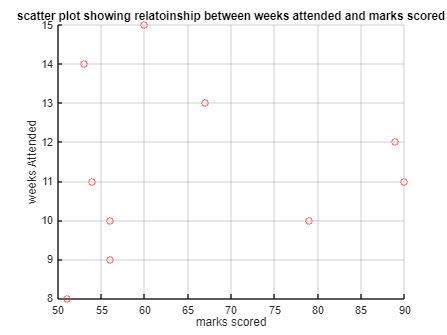


scatter(MarksScored,WeeksAttended,"r");
xlabel("marks scored");
ylabel("weeks Attended");
title("scatter plot showing relatoinship between weeks attended and marks scored");
grid on;

## relationhip of age and marks scored


scatter(Age,MarksScored,"magenta");

Unrecognized function or variable 'Age'.

xlabel("age");
ylabel("mark scored");
title("scatter plot showing age of student against their markes");
grid on;


Bar Graph

x = categorical(Name)
y = MarksScored
bar(x,y,"g");
title("A bar graph showing students and their marks");
ylabel("Marks Scored");
